# COVID-19 Linearization Example

Data is accurate as of 5 May 2020

Created on: 5 May 2020

Created by: Samuel Bechara, PhD

clc;clear;close all;
format long g;
load covidData.mat

## Initial Plotting

The variable `days` is the number of days since 20 Jan 2020

days = [1:length(cases)];
days = days';

% lets plot all the data and consider certain ranges...
plot(days,deaths,'r')
grid
title('Confirmed Deaths from COVID-19 in USA');
x_TITLE = 'Days since 20 Jan 2020';
xlabel(x_TITLE)
ylabel('Deaths');

## What does "flattening the curve" mean?

Lets look at log scale...


logDeaths = log10(deaths);
figure
plot(days,logDeaths, 'm')
xlabel(x_TITLE)
ylabel('Deaths Log Scale')
grid
xlim([0 110])
title('Deaths from Covid19 Log Scale')

## Looking at a region

lets only consider what happens between day 50 and 80

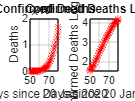

figure
% Can easily change these dates and will work downstream in code
lowDate = 50;
highDate = 80;
days = days(lowDate:highDate);
deathsAll = deaths;
deaths =  deaths(lowDate:highDate);
logDeathsAll =  logDeaths;
logDeaths = logDeaths(lowDate:highDate);

subplot(1,2,1)
plot(days,deaths,'r*')
grid
title('Confirmed Deaths')
xlabel(x_TITLE)
ylabel('Deaths')
subplot(1,2,2)
plot(days,logDeaths, 'r*')
title('Confirmed Deaths Log Scale')
grid
xlabel(x_TITLE)
ylabel('Confirmed Deaths Log Scale')

## Linear Regression

n = length(days);
sxy = sum(days.*logDeaths);
sx = sum(days);
sy = sum(logDeaths);
sx2 = sum(days.^2);
sy2 = sum(logDeaths.^2);

% Normal Equations - See why it might be nice to make this function?
a1 = ((n*sxy-sx+sy)/(n*sx2-sx^2));
a0 = mean(logDeaths)-a1*mean(days)

a0 =          -156.226381081872



% R^2
sR = (sum(logDeaths - a0 - a1*days).^2)

sR =       7.27014210251684e-27


sT = (sum(logDeaths-mean(logDeaths).^2))

sT =          -174.291033842104




rsquare = sT-sR/sT

rsquare =          -174.291033842104



% Plot the regression and data


## IF we didn't slow the curve

deathsByMay6 = round(10^(a1*107+a0))

deathsByMay6 =      5.73386515419144e+105



% probably NOT true due to infection rate and other factors
% EXTRAPOLATING IS DANGEROUS AND NOT A GOOD IDEA